# ECSE403 LAB1

Jm=0.01;
b=0.001;
Ke=0.02;
Kt=0.02;
Ra=10;

s=tf('s');

%------------Question 1---------------------
H1 = (Kt/Ra)/(Jm*s+(b+Kt*Ke/Ra))


H1 =
 
       0.002
  ----------------
  0.01 s + 0.00104
 
Continuous-time transfer function.



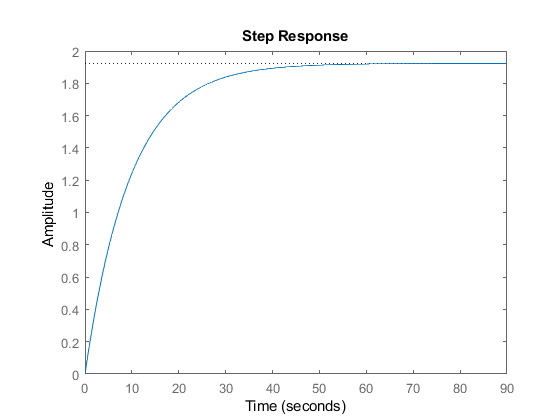

%------------Question 2---------------------
stepplot(H1)

stepinfo(H1)

ans = struct with fields:
        RiseTime: 21.1251
    SettlingTime: 37.6161
     SettlingMin: 1.7394
     SettlingMax: 1.9230
       Overshoot: 0
      Undershoot: 0
            Peak: 1.9230
        PeakTime: 101.4023



%------------Question 5---------------------
H2 = (Kt/Ra)/(Jm*s^2+(b+Kt*Ke/Ra)*s)


H2 =
 
         0.002
  --------------------
  0.01 s^2 + 0.00104 s
 
Continuous-time transfer function.



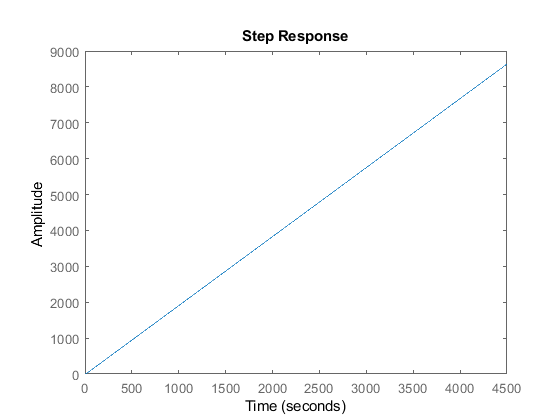

stepplot(H2)

stepinfo(H2)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf



%------------Question 6---------------------
H1c= H1/(1+H1)


H1c =
 
          2e-05 s + 2.08e-06
  -----------------------------------
  0.0001 s^2 + 4.08e-05 s + 3.162e-06
 
Continuous-time transfer function.



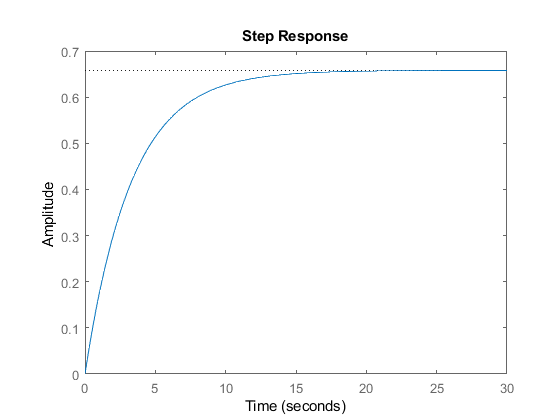

stepplot(H1c)

stepinfo(H1c)

ans = struct with fields:
        RiseTime: 7.2270
    SettlingTime: 12.8687
     SettlingMin: 0.5951
     SettlingMax: 0.6579
       Overshoot: 0
      Undershoot: 0
            Peak: 0.6579
        PeakTime: 34.6903



%------------Question 7---------------------

H1cp1= (0.1*H1)/(1+0.1*H1)


H1cp1 =
 
          2e-06 s + 2.08e-07
  ----------------------------------
  0.0001 s^2 + 2.28e-05 s + 1.29e-06
 
Continuous-time transfer function.



stepplot(H1cp1)

hold on

H1cp2= (1*H1)/(1+1*H1)


H1cp2 =
 
          2e-05 s + 2.08e-06
  -----------------------------------
  0.0001 s^2 + 4.08e-05 s + 3.162e-06
 
Continuous-time transfer function.



stepplot(H1cp2)
hold on

H1cp3= (10*H1)/(1+10*H1)


H1cp3 =
 
          0.0002 s + 2.08e-05
  ------------------------------------
  0.0001 s^2 + 0.0002208 s + 2.188e-05
 
Continuous-time transfer function.



stepplot(H1cp3)
hold on

H1cp4= (100*H1)/(1+100*H1)


H1cp4 =
 
          0.002 s + 0.000208
  -----------------------------------
  0.0001 s^2 + 0.002021 s + 0.0002091
 
Continuous-time transfer function.



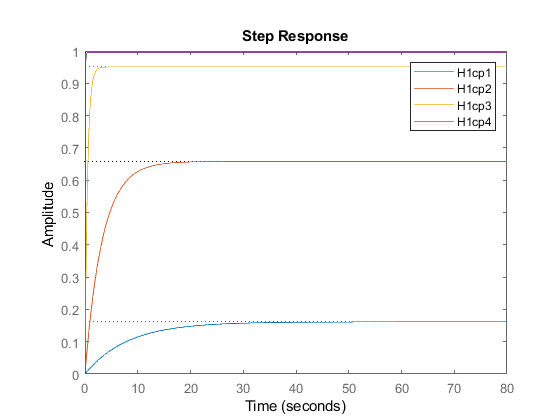

stepplot(H1cp4)
legend('H1cp1', 'H1cp2','H1cp3', 'H1cp4')
hold off


%------------Question 8---------------------

H2cp1= (0.1*H2)/(1+0.1*H2)


H2cp1 =
 
                  2e-06 s^2 + 2.08e-07 s
  ------------------------------------------------------
  0.0001 s^4 + 2.08e-05 s^3 + 3.082e-06 s^2 + 2.08e-07 s
 
Continuous-time transfer function.



stepplot(H2cp1)
stepinfo(H2cp1)

ans = struct with fields:
        RiseTime: 10.0198
    SettlingTime: 76.1727
     SettlingMin: 0.9166
     SettlingMax: 1.2888
       Overshoot: 28.8756
      Undershoot: 0
            Peak: 1.2888
        PeakTime: 23.9115


hold on

H2cp2= (1*H2)/(1+1*H2)


H2cp2 =
 
                  2e-05 s^2 + 2.08e-06 s
  ------------------------------------------------------
  0.0001 s^4 + 2.08e-05 s^3 + 2.108e-05 s^2 + 2.08e-06 s
 
Continuous-time transfer function.



stepplot(H2cp2)
stepinfo(H2cp2)

ans = struct with fields:
        RiseTime: 2.5544
    SettlingTime: 72.2175
     SettlingMin: 0.5212
     SettlingMax: 1.6921
       Overshoot: 69.2106
      Undershoot: 0
            Peak: 1.6921
        PeakTime: 7.0248


hold on

H2cp3= (10*H2)/(1+10*H2)


H2cp3 =
 
                 0.0002 s^2 + 2.08e-05 s
  ------------------------------------------------------
  0.0001 s^4 + 2.08e-05 s^3 + 0.0002011 s^2 + 2.08e-05 s
 
Continuous-time transfer function.



stepplot(H2cp3)
stepinfo(H2cp3)

ans = struct with fields:
        RiseTime: 0.7580
    SettlingTime: 73.6468
     SettlingMin: 0.2064
     SettlingMax: 1.8908
       Overshoot: 89.0836
      Undershoot: 0
            Peak: 1.8908
        PeakTime: 2.2214


hold on

H2cp4= (100*H2)/(1+100*H2)


H2cp4 =
 
                 0.002 s^2 + 0.000208 s
  -----------------------------------------------------
  0.0001 s^4 + 2.08e-05 s^3 + 0.002001 s^2 + 0.000208 s
 
Continuous-time transfer function.



stepplot(H2cp4)
stepinfo(H2cp4)

ans = struct with fields:
        RiseTime: 0.2351
    SettlingTime: 75.1704
     SettlingMin: 0.0705
     SettlingMax: 1.9641
       Overshoot: 96.4128
      Undershoot: 0
            Peak: 1.9641
        PeakTime: 0.7025


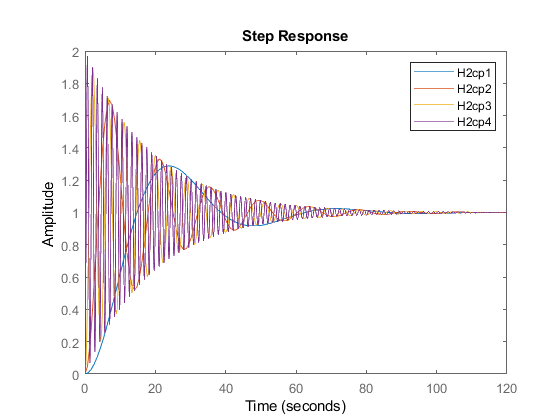

legend('H2cp1', 'H2cp2','H2cp3', 'H2cp4')
hold off

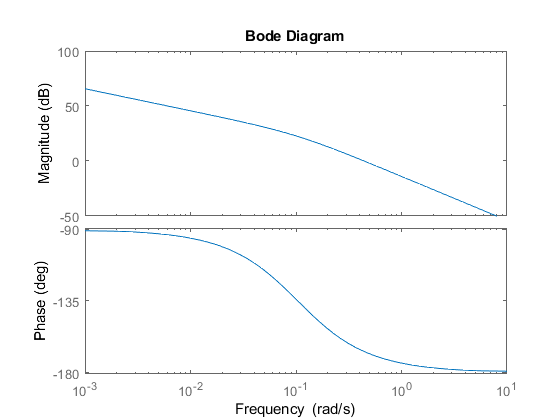



%------------Question 11---------------------

bodeplot(H2)

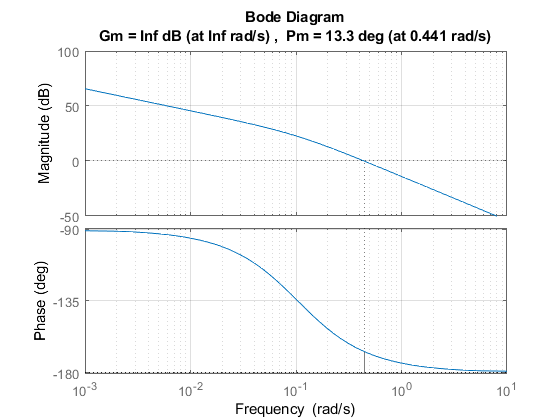

margin(H2)
grid on

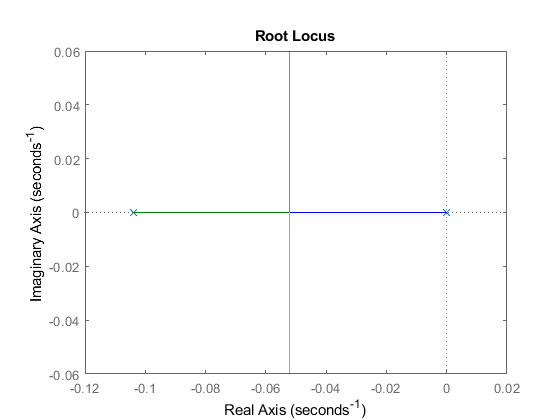


%------------Question 12---------------------
rlocus(H2)


%------------Question 13---------------------

K13= (s+0.35)/(s+0.75)


K13 =
 
  s + 0.35
  --------
  s + 0.75
 
Continuous-time transfer function.




H13= (K13*H2)/(1+K13*H2)


H13 =
 
                  2e-05 s^4 + 2.408e-05 s^3 + 7.538e-06 s^2 + 5.46e-07 s
  --------------------------------------------------------------------------------------
  0.0001 s^6 + 0.0001708 s^5 + 0.0001085 s^4 + 3.74e-05 s^3 + 8.146e-06 s^2 + 5.46e-07 s
 
Continuous-time transfer function.



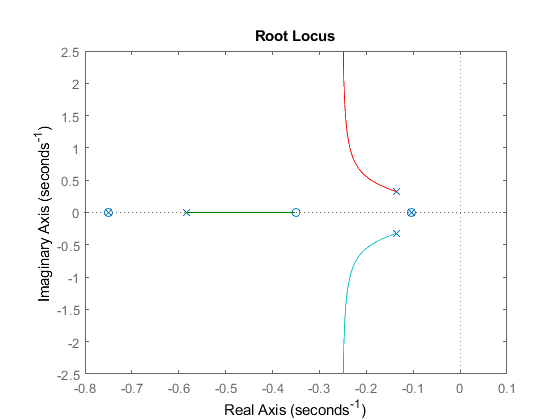


rlocus(H13)